# The AstroTable class

## Description:

The `AstroTable` class is a container for storing and manipulating astronomical tables. The class includes the basic functionality. The `AstroCatalog` class inherits from `AstroTable`. AstroTable inherits from `Component`.

Additional help is available using:

help AstroTable

  AstroTable handle class
  Package: @AstroTable
  Description: 
  Tested : Matlab R2018a
  Author : Eran O. Ofek (Mar 2021)
  Dependencies: @convert, @celestial
  Example : 
  Reliable: 2
 --------------------------------------------------------------------------

    Documentation for AstroTable
       doc AstroTable




help AstroTable.AstroTable

  Constrt an AstroTable object or transform AstCat/struct/ to AstroTable
  Input  : - If empty then construct and empty AstroTable object.
             If array/table, then construct an AstroTable object
                with this array in the Catalog property.
             If an AstCat/catCl object then convert it to
                AstroTable object.
             If file name or a cell array of file names, then
                attempt read data from files. Cell array
                contains a list of file names, while a single
                file may contain wild cards or gegular
                expressions.
           * ...,Key,Val,...
             'ColNames' - A cell array of column names.
                    If empty, try to use other inputs.
                    Default is {}.
             'ColUnits' - A cell array of column units.
                    If empty, try to use other inputs.
                    Default is {}.
             'UseRegExp' - Logical indicating if to use rege

% to see this file
open +manuals.AstroTable

Error using open (line 87)
File '+manuals.AstroTable' not found.

AstroTable.help

while a list of properties and methods is available by typing AstroTable followed by <tab>, or using

methods(AstroTable)

## Credit

If you are using this code or products in your scientific publication please give a reference to [Ofek (2014; ascl.soft 07005)](http://adsabs.harvard.edu/abs/2014ascl.soft07005O).

## License

Unless specified otherwise this code and products are released under the GNU general public license version 3.

## Installation

See [https://github.com/EranOfek/AstroPack](https://github.com/EranOfek/AstroPack)[ ](http://webhome.weizmann.ac.il/home/eofek/matlab/doc/install.html)for installation instruction and additional documentation.

## Class properties

- Catalog - Containing the table data. This can be eithre a matrix, or a table.

- ColNames - A cell array of column names.

- ColUnits - A cell array of column units.

- ColDesc - A cell array of column descriptions.

- SortByCol - An array of column indices, or a cell array of column names by which the catalog is sorted.

- IsSorted - A logical indicating if the catalog is sorted.

## Constructor

The `AstroTable` constructor can be used to generate empty objects, or load tables into an `AstroTable` object. A few examples:

% create a single element AstroTable with an empty Catalog.
AC = AstroTable
% Create a 2x2 AstroTable with an empty Catalog
AC = AstroTable([2 2])
% Created a 1x2 AstroTable. In each catalog store a rand(10,2) matrix
AC = AstroTable({rand(10,2),rand(10,2)})
% THe same as the previous line + set the Column names to 'a' and 'b'
AC = AstroTable({rand(10,2),rand(10,2)},'ColNames',{'a','b'});
% store tables
AC=AstroTable({array2table(rand(10,2))});
% Create an AstCat object (an old version of AstroTable)
A = AstCat;
A(1).Cat=rand(10,2);
A(2).Cat=rand(10,2); A(1).ColCell={'RA','Dec'};
A(1).ColUnits={'rad','rad'};
% read the AstCat object and convert it to AstroTable
AC = AstroTable(A);
% read from a FITS table
AC=AstroTable('asu.fit','HDU',2);

## Setters and getters

The setters and getters will set the IsSorted to false when a Catalog is changed. Furthermore, when the ColNames is modified, if the Catalog property contains a table, it will updated accordingly.

## Static methods

- defaultColNames - Generate a cell array of defalt column names - e.g., {'Var1', 'Var2',...}

- compareColNames - compare two cell arrays of column names.

- insertColumn - Insert a single column into a matrix, table, or a cell array.

- searchSynonym - Find the first appearance of a synonym in a cell array.

- unitTest - unitTest for the class

#### Examples

% test the class
AstroTable.unitTest

## Methods

### General methods

- sizeCatalog - Return the number o rows and columns in all elements in an AstroTable object.

- isemptyCatalog - Return true if Catalog data in AstroTable object is empty, otherwise false.

- deleteCatalog - delete the content of an AstroTable object.

- array2table - Convert catalog data in AstroTable to table forma.

- table2array - Convert catalog data in AstroTable to array format

#### Examples

AT = AstroTable({rand(100,2),rand(50,2)},'ColNames',{'RA','Dec'});
% return the size of the two catalogs in AT
[Nrow, Ncol]=AT.sizeCatalog

Nrow =    100    50


Ncol =      2     2


% check if each catalog is empty
AT.isemptyCatalog

ans = 1x2 logical array
   0   0


% delete the second catalog
AT(2).deleteCatalog;
% check if each catalog is empty
AT.isemptyCatalog

ans = 1x2 logical array
   0   1


### Columns information

- isColumn - Return true if a name is an existing column name in an AstroTable object.

- colname2ind - Convert column names to column indicet.

- colind2name - Return column names corresponding to column indices.

- colnameDict2ind - Given a list of column names, select the first that appear in Table.

- col2struct - Return structure array with column names in field and index in values.

- isColIdentical - Check if ColNames in an AstroTable object is identical to another ColNames

#### Examples

AT = AstroTable({rand(100,2),rand(50,2)},'ColNames',{'RA','Dec'});
% check if RA column exist in each catalog
AT.isColumn('RA')

ans = 1x2 logical array
   1   1


% colname2ind works on a single element object - return the index of 'Dec'
% column
AT(1).colname2ind('Dec')

ans =      2


% for two column names
AT(2).colname2ind({'Dec','RA'})

ans =      2     1


% search for the first appearance of a name in column, and return the
% column index (in the example, this is the Dec column)
AT(1).colnameDict2ind({'DECJ2000','Dec2000','Dec'})

ans =      2


% like colname2ind, but for multi element objects
% return a struct array with the column indices
St=AT.col2struct

St = 1x2 struct array with fields:
    RA
    Dec


% compare the column names to a cell array, for each element:
AT.isColIdentical({'a'})

ans = 1x2 logical array
   0   0


AT.isColIdentical({'RA','Dec'})

ans = 1x2 logical array
   1   1


### Columns and Data retrival and editing

- getCol - Get a catalog columns by index or names

- insertCol - Insert columns to AstroTable object

- replaceColNames - Replace column names in AstroTable object

- replaceCol - Replace columns in AstroTable

- deleteCol - Delete columns fron an AstroTable object.

#### Examples

AT = AstroTable({rand(100,2),rand(50,2)},'ColNames',{'RA','Dec'});
% return the content of the column named 'Dec'
AT(1).getCol('Dec')

ans =        0.2359
      0.30428
      0.30868
      0.69094
       0.5565
      0.58076
      0.61524
      0.55782
        0.358
     0.035376


% add a new column named 'NewCol to the first element in AT, after the last
% column (i.e., Inf).
AT(1).insertCol(rand(100,1),Inf,'NewCol')

ans =   AstroTable with properties:

      Catalog: [100x3 double]
     ColNames: {'RA'  'Dec'  'NewCol'}
     ColUnits: {''  ''  ''}
      ColDesc: {}
    SortByCol: []
     IsSorted: 0
         Name: []
        Owner: []
         Uuid: []
          Tag: []
       MapKey: []
       Config: [1x1 Configuration]
          Log: [1x1 MsgLogger]
    DebugMode: 1
     UserData: []


% replace column names {'RA','Dec','NewCol'} with {'RA','Dec','Mag'} at
% positions 1 to 3:
AT(1).replaceColNames([1:3], {'RA','Dec','Mag'})

ans =   AstroTable with properties:

      Catalog: [100x3 double]
     ColNames: {'RA'  'Dec'  'Mag'}
     ColUnits: {''  ''  ''}
      ColDesc: {}
    SortByCol: []
     IsSorted: 0
         Name: []
        Owner: []
         Uuid: []
          Tag: []
       MapKey: []
       Config: [1x1 Configuration]
          Log: [1x1 MsgLogger]
    DebugMode: 1
     UserData: []


% delete one or more columns by name or index
AT(1).deleteCol('Mag')

ans =   AstroTable with properties:

      Catalog: [100x2 double]
     ColNames: {'RA'  'Dec'}
     ColUnits: {''  ''}
      ColDesc: {}
    SortByCol: []
     IsSorted: 0
         Name: []
        Owner: []
         Uuid: []
          Tag: []
       MapKey: []
       Config: [1x1 Configuration]
          Log: [1x1 MsgLogger]
    DebugMode: 1
     UserData: []


AT.deleteCol({'RA','Dec'})

ans =   1x2 AstroTable array with properties:

    Catalog
    ColNames
    ColUnits
    ColDesc
    SortByCol
    IsSorted
    Name
    Owner
    Uuid
    Tag
    MapKey
    Config
    Log
    DebugMode
    UserData


% now, the two catalogs are empty:
AT.isemptyCatalog

ans = 1x2 logical array
   1   1


### Table Merging

- merge - Merge table/matrices in multiple AstroTable elements

#### Examples

AT = AstroTable({rand(100,2),rand(50,2)},'ColNames',{'RA','Dec'});
% merge the two catalogs into one
New = merge(AT)

New =   AstroTable with properties:

      Catalog: [150x2 double]
     ColNames: {'RA'  'Dec'}
     ColUnits: {}
      ColDesc: {}
    SortByCol: []
     IsSorted: 0
         Name: []
        Owner: []
         Uuid: []
          Tag: []
       MapKey: []
       Config: [1x1 Configuration]
          Log: [1x1 MsgLogger]
    DebugMode: 1
     UserData: []


% add two new columns to the New catalog
New.insertCol(rand(150,2),Inf,{'a','b'})

### Table sorting

- sortrows - Sort AstroTable objects by some column names/indices.

- flipud - flip up-down all catalogs in AstroTable object (set IsSorted to false)

#### Examples

AT = AstroTable({rand(100,2),rand(50,2)},'ColNames',{'RA','Dec'});
% check if sorted
AT.IsSorted

ans = logical
   0


ans = logical
   0


% sort by Dec
AT.sortrows('Dec')

ans =   1x2 AstroTable array with properties:

    Catalog
    ColNames
    ColUnits
    ColDesc
    SortByCol
    IsSorted
    Name
    Owner
    Uuid
    Tag
    MapKey
    Config
    Log
    DebugMode
    UserData


% check if sorted
AT.IsSorted

ans = logical
   1


ans = logical
   1


% flip
AT.flipud

ans =   1x2 AstroTable array with properties:

    Catalog
    ColNames
    ColUnits
    ColDesc
    SortByCol
    IsSorted
    Name
    Owner
    Uuid
    Tag
    MapKey
    Config
    Log
    DebugMode
    UserData


### Functions on tables

- funUnary - Apply an unary function to columns of a catalog

- min - Calculate the min value of all requested columns names/indices. Default is for all columns.

- max - Calculate the max value of all requested columns names/indices. Default is for all columns.

#### Examples

AT = AstroTable({rand(100,2),rand(50,2)},'ColNames',{'RA','Dec'});
% min on all columns
% The output is a matrix of size [Number of elements X number of columns]
min(AT)

ans =      0.010109     0.062958
     0.010109     0.062958


max(AT(1))

ans =       0.98601      0.99258


### Queries

- query - Query an AstroTable object

- queryRange - Query catalog by columns in range (without using eval).

#### Examples

AT = AstroTable({rand(100,2),rand(50,2)},'ColNames',{'RA','Dec'});
% operate a query string using column names
New = query(AT,'RA>0.1 & Dec<0.2')

New =   1x2 AstroTable array with properties:

    Catalog
    ColNames
    ColUnits
    ColDesc
    SortByCol
    IsSorted
    Name
    Owner
    Uuid
    Tag
    MapKey
    Config
    Log
    DebugMode
    UserData


AT.sizeCatalog

ans =    100    50


New.sizeCatalog

ans =     17     6


% a faster query in range
AT.queryRange('RA',[0.1 0.2])

ans =   1x2 AstroTable array with properties:

    Catalog
    ColNames
    ColUnits
    ColDesc
    SortByCol
    IsSorted
    Name
    Owner
    Uuid
    Tag
    MapKey
    Config
    Log
    DebugMode
    UserData


AT.sizeCatalog

ans =      8     5


% use multiple ranges
AT.queryRange('RA',[0.1 0.9],'Dec',[0.1 0.9])

ans =   1x2 AstroTable array with properties:

    Catalog
    ColNames
    ColUnits
    ColDesc
    SortByCol
    IsSorted
    Name
    Owner
    Uuid
    Tag
    MapKey
    Config
    Log
    DebugMode
    UserData


AT.sizeCatalog

ans =      7     4


% value in columns equal some value
AT.queryRange('RA',0.5)

ans =   1x2 AstroTable array with properties:

    Catalog
    ColNames
    ColUnits
    ColDesc
    SortByCol
    IsSorted
    Name
    Owner
    Uuid
    Tag
    MapKey
    Config
    Log
    DebugMode
    UserData


AT.sizeCatalog

ans =      0     0


### Ploting

- plotFun - Operate a graphical function on AstroTable

- plot - plot function for AstroTable objects

#### Examples

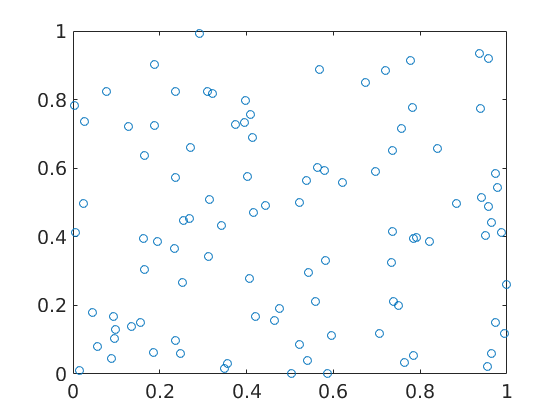

AT = AstroTable({rand(100,2),rand(50,2)},'ColNames',{'RA','Dec'});
% plot RA vs. Dec
AT(1).plot({'RA','Dec'},'o')

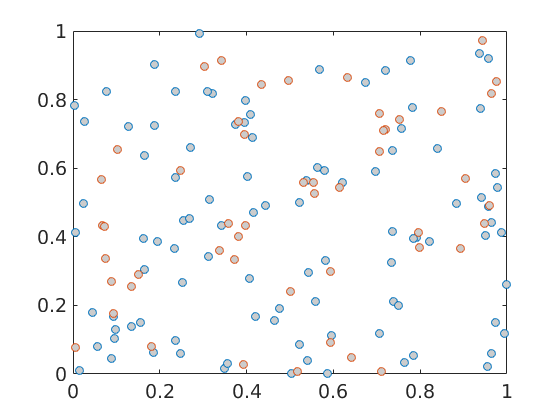

% overlay both elements on top of each others
AT.plot({'RA','Dec'},'o','MarkerFaceColor',[0.8 0.8 0.8])

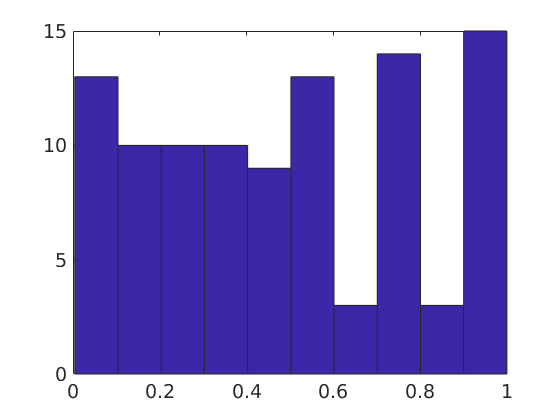

% apply a general plotting function on AstroTable:
AT(1).plotFun(@hist,{'RA'})